# Explore the Eigenaxis representation of angular pose

This tutorial demonstrates how to use the `bh_eul_eigenaxis_CLS` for representing the Eigenaxis approach of angular pose 

## **Import the package:**

import bh_rots_PKG.*

## A refresher on  DCM - via Euler angles

syms phi theta psi

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi],'SYM');

And look at what you have - here's the DCM

- $^Bv = {^BR_G}.^Gv$      where   $ {^BR_G} = 
R_{3X}(Roll) \enspace . \enspace 
R_{2Y}(Pitch)\enspace . \enspace R_{1Z}(Yaw)$   

tmp_R3R2R1 = OBJ_pass_rot.get_R3R2R1

$$tmp\_R3R2R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here are the 3 individual PASSIVE rotation matrices:

tmp_R1 = OBJ_pass_rot.get_R1

$$tmp\_R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

tmp_R2 = OBJ_pass_rot.get_R2

$$tmp\_R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

tmp_R3 = OBJ_pass_rot.get_R3

$$tmp\_R3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Create a reference DCM - via Euler angles

In case you want to run this section again AFTER you've already run the script:

import bh_rots_PKG.*

#### Specify the angles

ref_yaw_deg   = 190;
ref_pitch_deg = 60;
ref_roll_deg  = 40;
ref_YPR_deg   = [ref_yaw_deg, ref_pitch_deg, ref_roll_deg];

#### Create the DCM

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, ref_YPR_deg,'DEGREES');
 
 ref_DCM_bRg  = OBJ_pass_rot.get_R3R2R1 

ref_DCM_bRg =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Plot stuff

ans = 12.0001

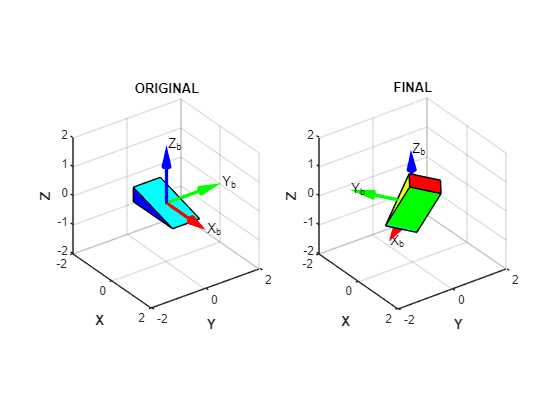

 OBJ_pass_rot.plot_pair();

Plot more stuff

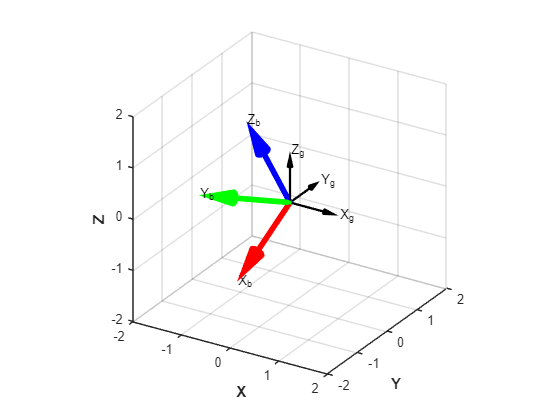

figure;
    hax = axes;
    OBJ_pass_rot.plot("hax",hax,"tf_showcar",false, "tf_show_gframe",true);
    view([31.47 26.16])

## Explore the Eigenaxis representation - part 1

In case you want to run this section again AFTER you've already run the script:

import bh_rots_PKG.*

### Play with the Eigenaxis object - create using a DCM:

Say you have a DCM:

ref_DCM_bRg 

ref_DCM_bRg =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Create the Eigenaxis object:

 OBJ_ee = bh_eul_eigenaxis_CLS(ref_DCM_bRg)

OBJ_ee =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.9424
    DCM_B_given_A: [3×3 double]
        theta_deg: 168.5871
           e_axis: [-0.4963 0.2554 0.8297]
      vis_DCM_bRg: [3×3 double]


So what is the **Eigenaxis** and **theta **and the** DCM**

OBJ_ee.e_col.'

ans =    -0.4963    0.2554    0.8297


OBJ_ee.theta_rad

ans = 2.9424

OBJ_ee.DCM_B_given_A

ans =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


### Play with the Eigenaxis object - create using E_col and theta

Alternatively construct the Eigenaxis by defining the 

- UNIT vector (RH rule for positive rotation)

- the angle of rotation

ee_col       = OBJ_ee.e_col;
ee_theta_rad = OBJ_ee.theta_rad;

OBJ_ee_new   = bh_eul_eigenaxis_CLS(ee_col, ee_theta_rad)

OBJ_ee_new =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.9424
    DCM_B_given_A: [3×3 double]
        theta_deg: 168.5871
           e_axis: [-0.4963 0.2554 0.8297]
      vis_DCM_bRg: [3×3 double]


Retrieve the DCM from the Eigenaxis parameters

ee_DCM = OBJ_ee_new.DCM_B_given_A

ee_DCM =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Plot stuff 

ans = 14.0001

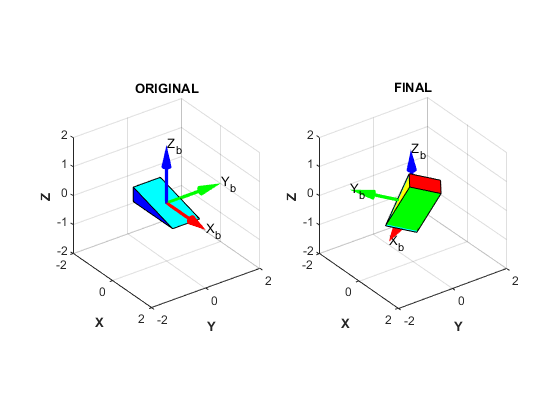

OBJ_ee_new.plot_pair();

Plot more stuff

hax = OBJ_ee_new.plot_ee();

ans = 16.0001

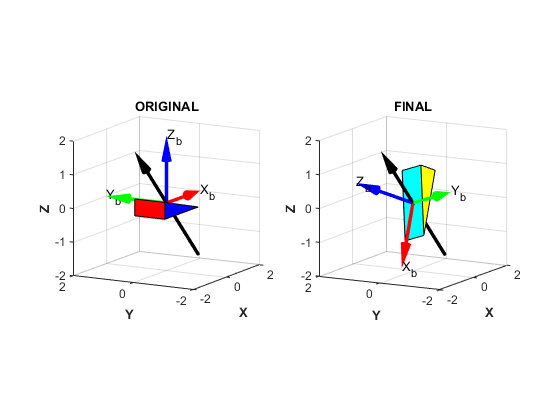

    view(hax(1),[-60.96 11.76])
    view(hax(2),[-60.96 11.76])

    %linkprop(hax,{'CameraPosition','CameraUpVector'})

And make an animation 

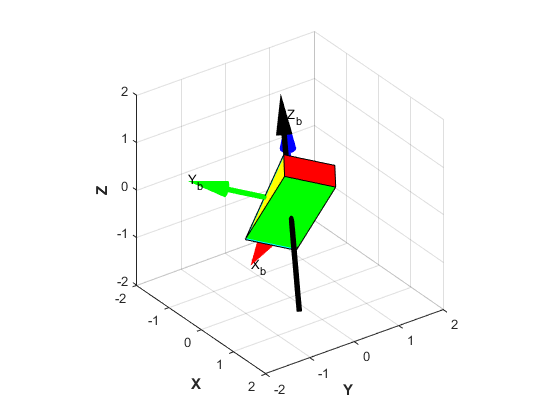

OBJ_ee_new.animate()

## Explore the Eigenaxis representation - part 2a

Once you define the Eigenaxis, you can then define the "signed" angle about this axis. So the following 2 cases are identical

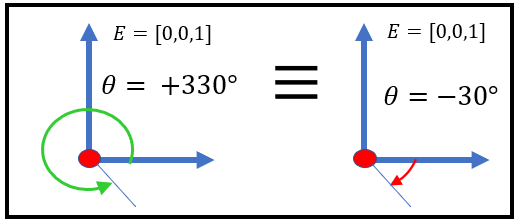

Check it out:

ee_col       = [5;5;5]/norm([5;5;5]); % the Eigenaxis
ee_theta_rad = deg2rad(330);
OBJ_ee       = bh_eul_eigenaxis_CLS(ee_col, ee_theta_rad)

OBJ_ee =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 5.7596
    DCM_B_given_A: [3×3 double]
        theta_deg: 330
           e_axis: [0.5774 0.5774 0.5774]
      vis_DCM_bRg: [3×3 double]


Now ask for the EQUIVALENT Eigenaxis parameters for the case $\theta \in \left\lbrack -\pi \;,\pi \;\right\rbrack$

OBJ_ee_alternate = OBJ_ee.convert_angle_to_pm_pi()

OBJ_ee_alternate =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: -0.5236
    DCM_B_given_A: [3×3 double]
        theta_deg: -30.0000
           e_axis: [0.5774 0.5774 0.5774]
      vis_DCM_bRg: [3×3 double]


Note:

-  A rotation of +330 degrees about +E-axis ... is equivalent to a -30 degree rotation about the SAME +E_axis

And confirming by comparing the DCM of both cases:

DCM_A = OBJ_ee.DCM_B_given_A

DCM_A =     0.9107   -0.2440    0.3333
    0.3333    0.9107   -0.2440
   -0.2440    0.3333    0.9107


DCM_B = OBJ_ee_alternate.DCM_B_given_A

DCM_B =     0.9107   -0.2440    0.3333
    0.3333    0.9107   -0.2440
   -0.2440    0.3333    0.9107


## Explore the Eigenaxis representation - part 2b

Here's another situation that shouldn't be surprising:

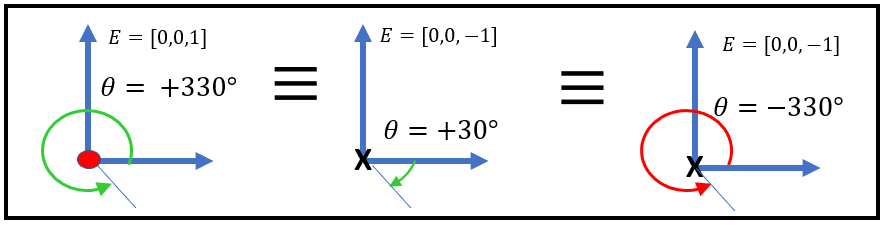

So ? All of the following are EQUIVALENT

- a $+330$ deg rotation about $+E_{\textrm{AXIS}}$

- a   $+30$ deg rotation about $-E_{\textrm{AXIS}}$

- a $-330$ deg rotation about $-E_{\textrm{AXIS}}$

ee_col    = [5;5;5;]/norm([5;5;5]);
case_p330 = bh_eul_eigenaxis_CLS(   ee_col, deg2rad(330)  )

case_p330 =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 5.7596
    DCM_B_given_A: [3×3 double]
        theta_deg: 330
           e_axis: [0.5774 0.5774 0.5774]
      vis_DCM_bRg: [3×3 double]


case_p30  = bh_eul_eigenaxis_CLS(  -1*ee_col, deg2rad( 30)  )

case_p30 =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 0.5236
    DCM_B_given_A: [3×3 double]
        theta_deg: 30.0000
           e_axis: [-0.5774 -0.5774 -0.5774]
      vis_DCM_bRg: [3×3 double]


case_n330  = bh_eul_eigenaxis_CLS(  -1*ee_col, deg2rad(-330) )

case_n330 =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: -5.7596
    DCM_B_given_A: [3×3 double]
        theta_deg: -330
           e_axis: [-0.5774 -0.5774 -0.5774]
      vis_DCM_bRg: [3×3 double]


And the DCMs are all the same:

case_p330.DCM_B_given_A

ans =     0.9107   -0.2440    0.3333
    0.3333    0.9107   -0.2440
   -0.2440    0.3333    0.9107


(case_p330.DCM_B_given_A - case_p30.DCM_B_given_A)

ans = 	1.0e+-15 *

   -0.2220   -0.2220    0.4441
    0.4441   -0.2220   -0.2220
   -0.2220    0.4441   -0.2220


(case_p330.DCM_B_given_A - case_n330.DCM_B_given_A)

ans =      0     0     0
     0     0     0
     0     0     0


## Explore the Eigenaxis representation - part 3

Here's another situation that shouldn't be surprising.  As previously discussed, the following situations are identical:

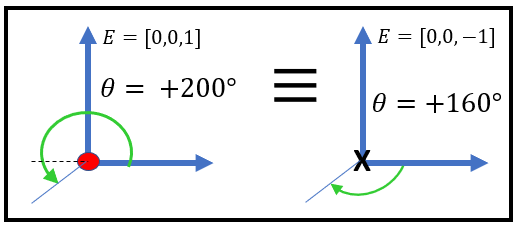

When you create an EigenAxis object by supplying a DCM, the Eigenaxis that gets returned will be for the case where $\theta$ is in the interval $\theta \in \left\lbrack 0,\;\;\pi \;\right\rbrack$

Create a DCM:

- $\theta ={200}^{\circ }$ about the axis $\left\lbrack 0,0,1\right\rbrack$

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [200, 0, 0],'DEGREES');
the_dcm      = OBJ_pass_rot.get_R3R2R1

the_dcm =    -0.9397   -0.3420         0
    0.3420   -0.9397         0
         0         0    1.0000


Create the EigenAxis object:

my_eig_obj = bh_eul_eigenaxis_CLS(the_dcm )

my_eig_obj =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.7925
    DCM_B_given_A: [3×3 double]
        theta_deg: 160.0000
           e_axis: [0 0 -1.0000]
      vis_DCM_bRg: [3×3 double]


NOTE how we have:

- $\theta ={160}^{\circ }$ about the axis $\left\lbrack 0,0,-1\right\rbrack$

And the DCM is the same:

my_eig_obj.DCM_B_given_A

ans =    -0.9397   -0.3420         0
    0.3420   -0.9397         0
         0         0    1.0000


## Explore the Eigenaxis representation - part 4

Recall the reference DCM that we've been playing with:

- 
$$^Bv = {^BR_G}.^Gv$$


ref_DCM_bRg

ref_DCM_bRg =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Create an Eigenaxis object from the DCM

OBJ_ee = bh_eul_eigenaxis_CLS(ref_DCM_bRg)

OBJ_ee =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.9424
    DCM_B_given_A: [3×3 double]
        theta_deg: 168.5871
           e_axis: [-0.4963 0.2554 0.8297]
      vis_DCM_bRg: [3×3 double]


What is the E-axis:

E_axis_G = OBJ_ee.e_col;
E_axis_G.'

ans =    -0.4963    0.2554    0.8297


NOw watch what happens when we multiply the E-axis by the DCM:

- 
$$^BE = {^BR_G}.^GE$$


E_axis_B = OBJ_ee.DCM_B_given_A * E_axis_G;
E_axis_B.'

ans =    -0.4963    0.2554    0.8297


And it's NOT surprising that $^BE =  {^GE}$ . Why ?  Because the Eigenaxis $E$ corresponds to the Eigenvector  $v$ of the DCM that has a corresponding eigenvalue of $\lambda =1$, ie:   $\left\lbrack A\right\rbrack \ldotp \overrightarrow{v} =\lambda \ldotp \overrightarrow{v}$   which in our case is $\left\lbrack \textrm{DCM}\right\rbrack \ldotp \overrightarrow{E} =\overrightarrow{E}$  

[mat_of_eig_vecs, mat_of_eig_values] = eig(OBJ_ee.DCM_B_given_A)

mat_of_eig_vecs =   -0.4963 + 0.0000i   0.0927 - 0.6068i   0.0927 + 0.6068i
   0.2554 + 0.0000i   0.6837 + 0.0000i   0.6837 + 0.0000i
   0.8297 + 0.0000i  -0.1550 - 0.3630i  -0.1550 + 0.3630i


mat_of_eig_values =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.9802 + 0.1979i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.9802 - 0.1979i


# Local subfunctions only beyond this point

 function LOC_plot_stuff(DCM_bRg, hfig, hax)
  % ALLOWED USAGE:
  %   >> LOC_plot_stuff(DCM)
  %   >> LOC_plot_stuff(DCM, hfig, hax)  
  
    if(1==nargin)
        hfig = figure;
        hax  = axes();
    end
 
    import bh_rots_PKG.bh_vehicle_CLS
 
    DCM_gRb = DCM_bRg.';    
    
    veh_OBJ = bh_vehicle_CLS();  
    %veh_OBJ.FaceAlpha = 0.5;
    veh_OBJ = veh_OBJ.rotate_using_gRb(DCM_gRb);
    
    % plot stuff
    veh_OBJ.plot_3D(hax);
    
 end